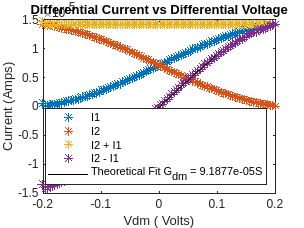

I1_35 = table2array(readtable("lab5_i1_str_3.5.csv"));
I2_35 = table2array(readtable("lab5_i2_str_3.5.csv"));
Vdm_35 = table2array(readtable("lab_5v_str_3.5.csv"));
Vdm_25 = table2array(readtable("lab_5v_str_2.5.csv"));
Vdm_45 = table2array(readtable("lab_5v_str_4.5.csv"));

epsil=5e-3;

I1_plus_I2 = I1_35 + I2_35;
I1_minus_I2 = I1_35 - I2_35;
plot(Vdm_35(:,1,:),I1_35(:,2,:),'*','DisplayName', 'I1');
hold on;
plot(Vdm_35(:,1,:),I2_35(:,2,:),'*','DisplayName', 'I2');
hold on
plot(Vdm_35(:,1,:),I1_plus_I2(:,2,:),'*','DisplayName', 'I2 + I1');
hold on
plot(Vdm_35(:,1,:),I1_minus_I2(:,2,:),'*', 'DisplayName', 'I2 - I1');
hold on;

Vdm_35_2 = Vdm_35(:,1,:);
I1_minus_I2_2 = I1_minus_I2(:,2,:);
linear_idx = Vdm_35_2() >= -0.1 & Vdm_35_2 <= 0.1;
lin_3_5=I1_minus_I2_2(linear_idx);
lin_vdm=Vdm_35_2(linear_idx);
[f2, l2, m2, b2, n2] = linefit(lin_vdm, lin_3_5, epsil);
fitline2 = m2 * lin_vdm + b2;
plot(lin_vdm, fitline2, "k", 'DisplayName', ['Theoretical Fit G_{dm} = ' num2str(m2) 'S']);

% Gdm = I1_minus_I2(:,2) ./ Vdm_35(:,2);
% % Fit a line of best fit for Gdm
% coefficients = polyfit(Vdm_35(:,1), Gdm, 1);
% xFit = linspace(min(Vdm_35(:,1)), max(Vdm_35(:,1)), 100);
% yFit = polyval(coefficients, xFit);
% 
% % Plot the line of best fit
% plot(xFit, yFit, 'r', 'LineWidth', 2, 'DisplayName', 'Line of Best Fit for G_{dm}');

% Add legend and title
legend('show', Location='southeast');
title('Differential Current vs Differential Voltage');
xlabel('Vdm ( Volts)');
ylabel('Current (Amps)');
print("-depsc","experiment_1_last_1.eps")

Second Plot

hold off;

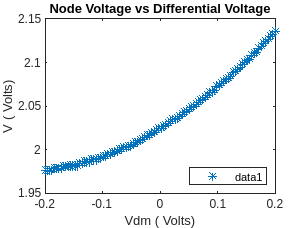

plot(Vdm_35(:,1,:),Vdm_35(:,2,:),'*');

legend('show', Location='southeast');
xlabel('Vdm ( Volts)');
ylabel('V ( Volts)');
title('Node Voltage vs Differential Voltage');
print("-depsc","experiment_1_last_2.eps")

Third Plot

hold off;

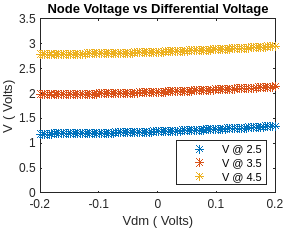

plot(Vdm_35(:,1,:),Vdm_25(:,2,:),'*', 'DisplayName',"V @ 2.5"); hold on; 
plot(Vdm_35(:,1,:),Vdm_35(:,2,:),'*', 'DisplayName',"V @ 3.5"); hold on;
plot(Vdm_35(:,1,:),Vdm_45(:,2,:),'*', 'DisplayName',"V @ 4.5");

legend('show', Location='southeast');
ylim([0,3.5]);
xlabel('Vdm ( Volts)');
ylabel('V ( Volts)');
title('Node Voltage vs Differential Voltage');
print("-depsc","experiment_1_last_3.eps")